alpha = 0.6;
wc = 0.9 * pi;
expected = 2/(1-alpha)

expected = 5


b = [1 0 -1];
a = [1 -1*(1+alpha)*cos(wc) alpha]

a =     1.0000    1.5217    0.6000




[h,w] = freqz(b, a)

h =    0.0000 + 0.0000i
   0.0000 + 0.0039i
   0.0000 + 0.0079i
   0.0000 + 0.0118i
   0.0000 + 0.0157i
   0.0001 + 0.0197i
   0.0001 + 0.0236i
   0.0002 + 0.0275i
   0.0002 + 0.0315i
   0.0003 + 0.0354i


w =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


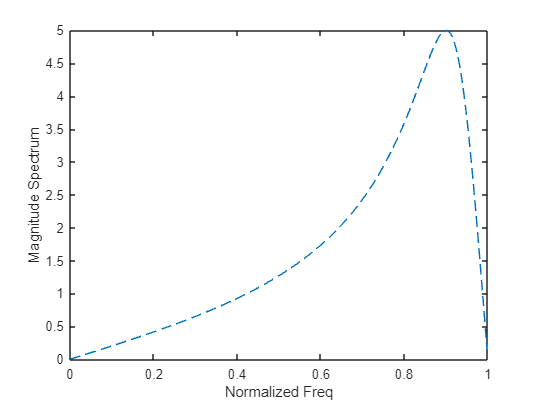



figure;
plot(w/pi, abs(h),LineStyle="--");
xlabel('Normalized Freq')
ylabel('Magnitude Spectrum')

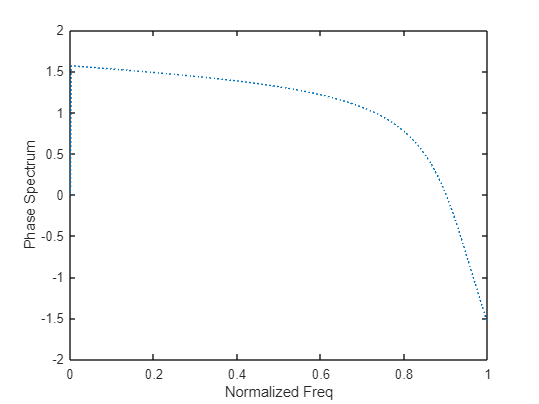


figure;
plot(w/pi, angle(h),LineStyle=":");
xlabel('Normalized Freq')
ylabel('Phase Spectrum')


[max_val, index] = max(abs(h))

max_val = 4.9999

index = 462


z = max_val == expected

ans = logical
   0


if z == 1
    disp('The given relation is true')
end
